% Make activity correlation matrix from RecICA_Temp written by NY

CompNum = 40;
Animal = 'tlx35'

Animal = 'tlx35'

Events = {'temp'}; % {'CueAligned', 'MovOnsetAligned','RewardAligned'}; % need to be modified
Initial = 'NY'; 
% Animals = {'tlx29', 'tlx30'}; 
Date = '221118';
Key = 'min';
Block = 1;
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\';

close all
clc

% load neural activity data
cd([working_directory Date filesep Initial '_' Animal ])
addpath([working_directory Date filesep Initial '_' Animal filesep 'ICA\ICA_40']);
load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],'RecICA_Temp','-mat');
samp_img = reshape(RecICA_Temp{Block},[128 128 size(RecICA_Temp{Block}, 2)])

samp_img = samp_img(:,:,1) =

    0.0469    0.0503    0.0337    0.0394    0.0373    0.0469    0.0528    0.0379    0.0487    0.0435    0.0560    0.0320    0.0413    0.0470    0.0409    0.0435    0.0433    0.0316    0.0367    0.0342    0.0369    0.0347    0.0229    0.0392    0.0402    0.0308    0.0422    0.0247    0.0321    0.0249    0.0339    0.0504    0.0334    0.0346    0.0353    0.0295    0.0193    0.0265    0.0369    0.0419    0.0380    0.0386    0.0320    0.0310    0.0395    0.0442    0.0322    0.0202    0.0329    0.0263    0.0334    0.0284    0.0404    0.0401    0.0451    0.0582    0.0457    0.0374    0.0387    0.0648    0.0606    0.0735    0.0836    0.0903    0.0744    0.0767    0.0870    0.0920    0.0792    0.0555    0.0582    0.0680    0.0428    0.0300    0.0360    0.0257    0.0202    0.0214    0.0222    0.0213    0.0150    0.0166    0.0158    0.0146    0.0172    0.0205    0.0301    0.0229    0.0306    0.0430    0.0376    0.0239    0.0252    0.0172    0.0337    0.0353    0.0309

imwrite(samp_img(:,:,1),sprintf('RecICA_Temp_%d.png', 1));

% set ROI to compare neural activity
brain_roi_name = ['A' 'B' 'C' 'D' 'E' 'F']

brain_roi_name = 'ABCDEF'

brain_roi = [[75, 15]; [106, 61]; [85, 82]; [49, 15]; [10, 57]; [45, 82]];
y_reverse = true; % True if brain_roi is specified by ImageJ
% set how many pixels expand
pix_exp = 2;

if y_reverse == true;
    for i = 1:length(brain_roi) 
        brain_roi(i,2) = 128 - brain_roi(i,2);
    end
end

RecICA_Temp_reshape = reshape(RecICA_Temp{Block},[128 128 size(RecICA_Temp{Block}, 2)]);
roi_activities = zeros(length(brain_roi),size(RecICA_Temp{Block}, 2));
% expand roi
for i = 1:length(brain_roi)    
    roi_RecICA_Temp = RecICA_Temp_reshape(brain_roi(i,1)-pix_exp:brain_roi(i,1)+pix_exp, brain_roi(i,2)-pix_exp:brain_roi(i,2)+pix_exp, :); 
    % take mean of neural activity
    mean_roi_activity = reshape(mean(mean(roi_RecICA_Temp)),[1 size(RecICA_Temp{Block}, 2)]);
    roi_activities(i,:) = mean_roi_activity;
end
% calculate correlation of neural activity
R_roi_act = corrcoef(transpose(roi_activities));

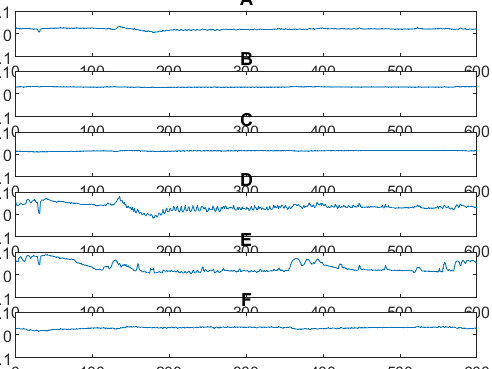

% plot neural activity of specific brain region
figure
% set(gcf,'color','k')
for i = 1:length(brain_roi) 
    subaxis(length(brain_roi),1,i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
%     clims = [-0.04 0.04];
%     image = ModePCA(:,mode);
%     imagesc(reshape(image,[128 128]),clims)
%     colormap jet;
%     axis square
%     axis off
    plot(roi_activities(i,:));
    title([brain_roi_name(i)]);
    ylim([-0.1 0.1]);
end
saveas(gcf,[Animal '_activity.png']);

% close all
% figure;


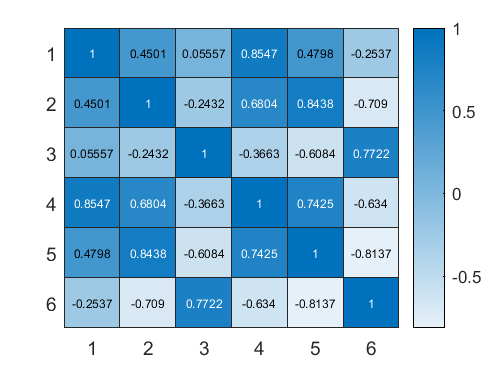

% plot correlation heatmap
figure;
% set(gcf,'color','w');
%     subaxis(4,5,mode, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
% clims = [0 0.8];
% image = RecICA_Temp{1}(:,1);
% imagesc(reshape(image,[128 128]),clims);
colormap jet;
heatmap(R_roi_act)
saveas(gcf,[Animal '_activity_correlation.png']);

% axis square;
% axis off;